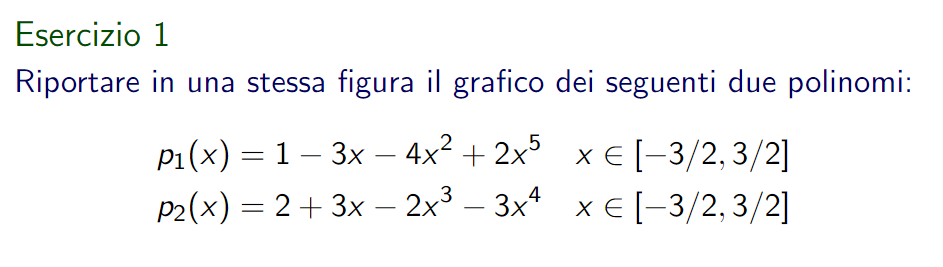

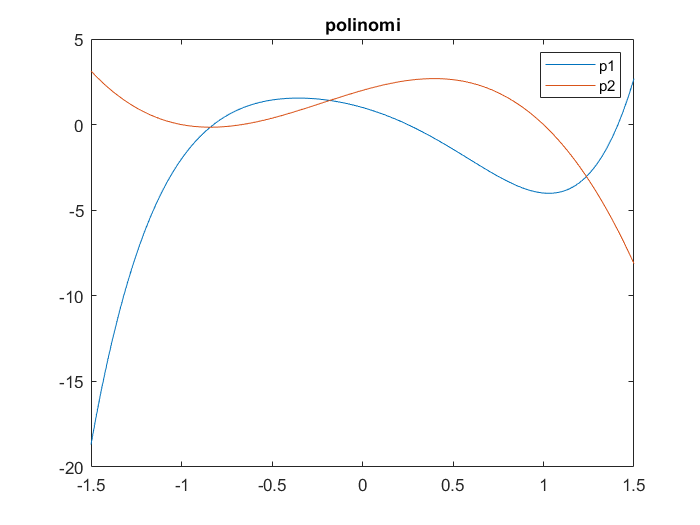

clear all
close all
c1 = [2 0 0 -4 -3 1];
c2 = [-3 -2 3 2];
x = linspace(-3/2,3/2,101);
p1 = polyval(c1,x);
p2 = polyval(c2,x);

plot(x,p1,x,p2)
title("polinomi")
legend("p1","p2")

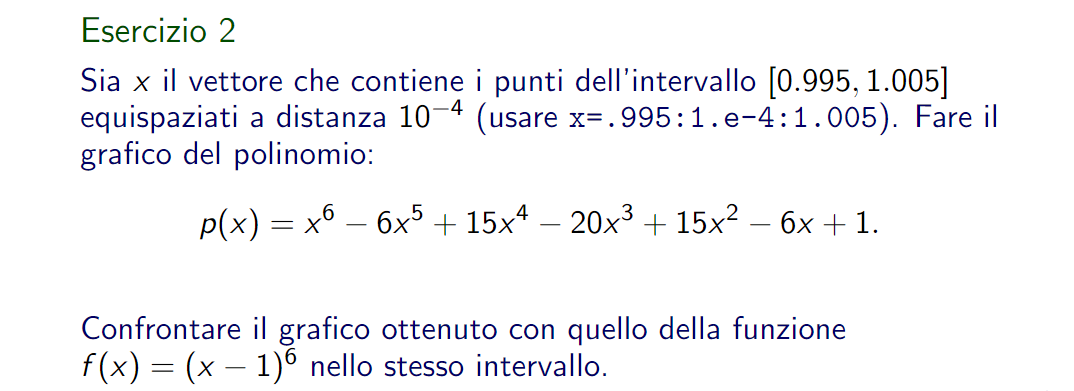

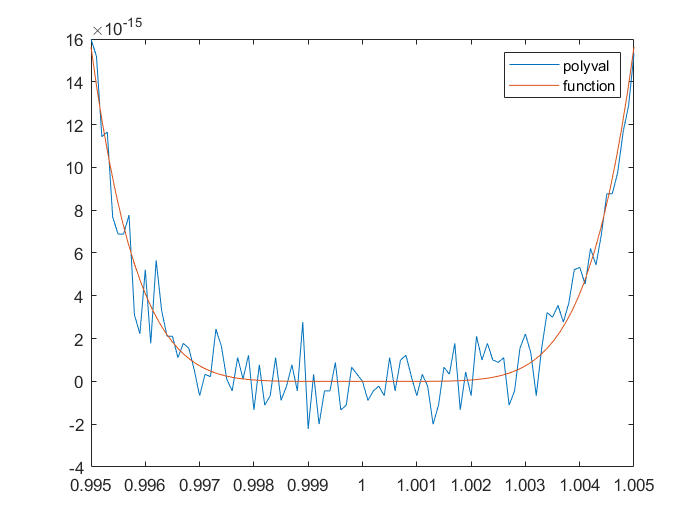

clear all
close all

x = 0.995:1.e-4:1.005;
c = [1 -6 +15 -20 +15 -6 1];
p = polyval(c,x);
plot(x,p)
hold on
f = @(x) (x-1).^6;
fplot(f,[0.995 1.005])
legend("polyval","function")

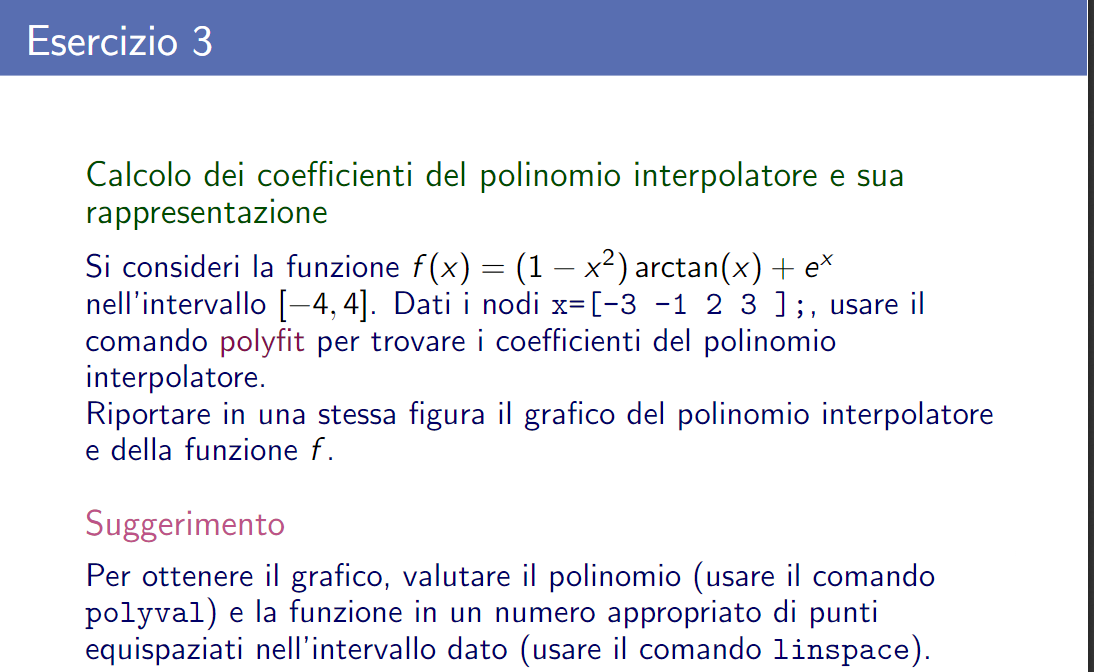

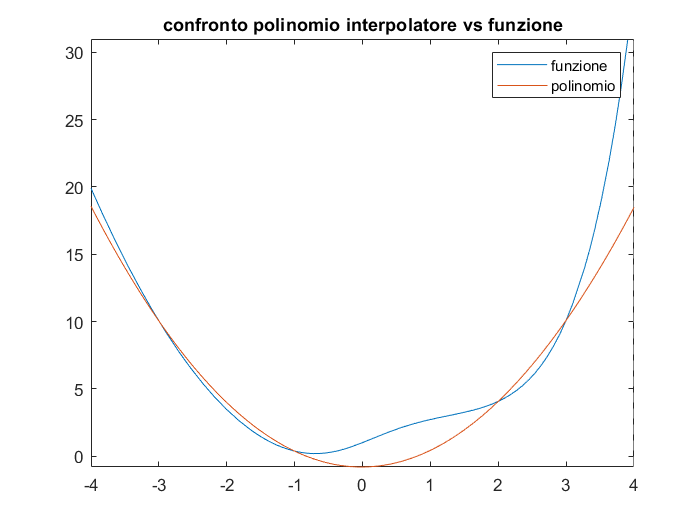

clear all
close all
f = @(x) (1-x.^2).*atan(x) + exp(x);
fplot(f,[-4 4])
hold on
x = [-3 -1 2 3];
xp = linspace(-4,4,101);
y = [f(-3) f(-1) f(2) f(3)];
c = polyfit(x,y,3);
p = polyval(c,xp);
plot(xp,p)
title("confronto polinomio interpolatore vs funzione")
legend("funzione","polinomio")

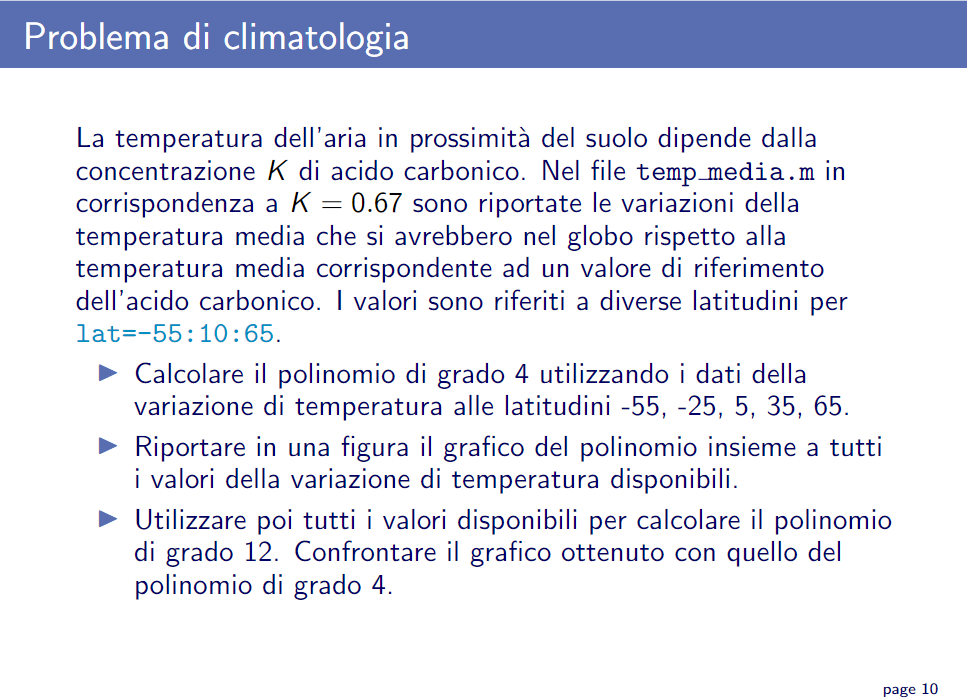

clear all
close all
temp_media
lat = [-55 -25 5 35 65];
y = [T(1,1) T(1,4) T(1,7) T(1,10) T(1,13)];
c = polyfit(lat,y,4);
lat_tot = -55:1:65;
p = polyval(c,lat_tot);
plot(lat_tot,p)
hold on
lat = -55:10:65;
c = polyfit(lat,T,12);

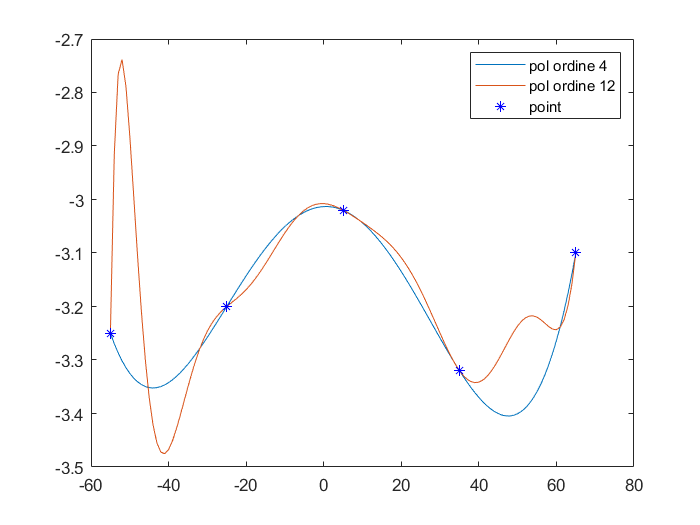

pt = polyval(c,lat_tot);
plot(lat_tot,pt)
lat = [-55 -25 5 35 65];
plot(lat,y,"*b")
legend("pol ordine 4","pol ordine 12","point")

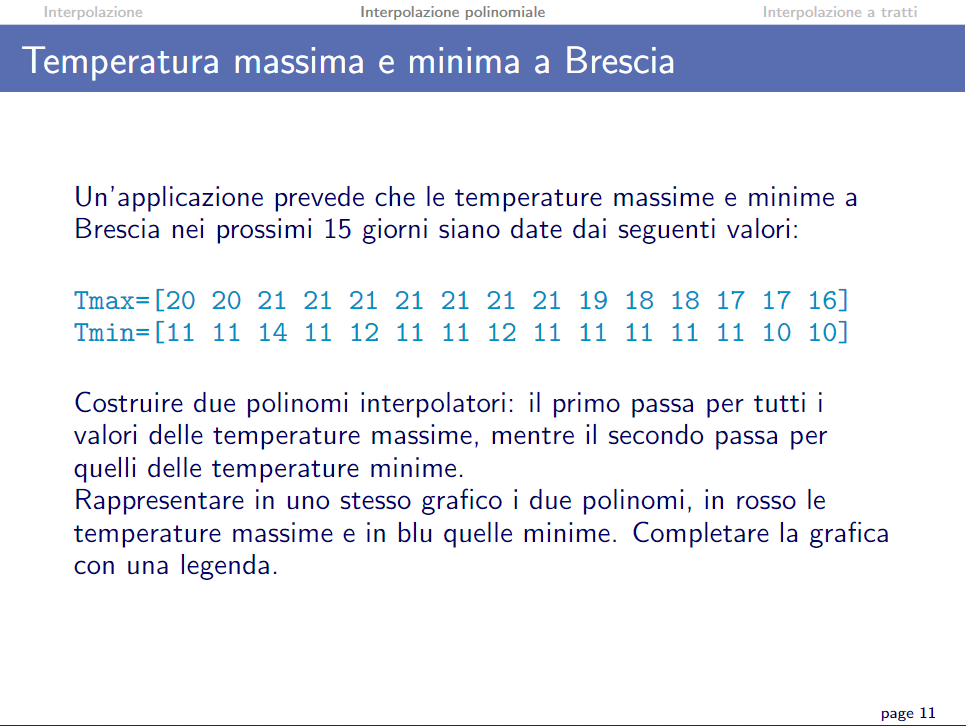

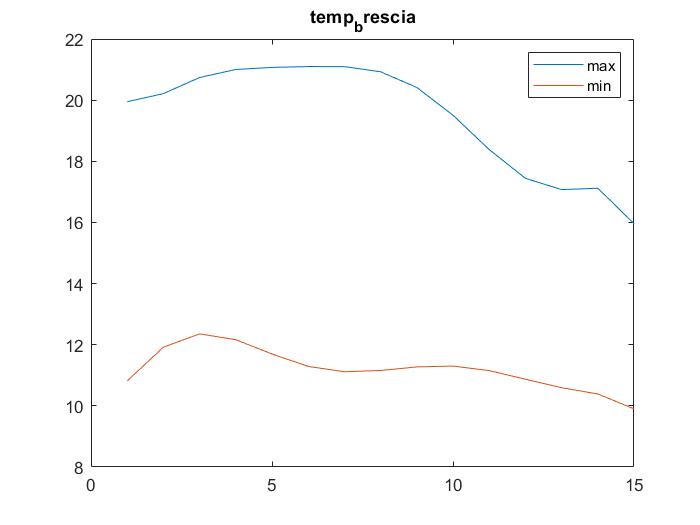

clear all
close all
T_BS
tempo = 1:1:15;
c = polyfit(tempo,Tmax,7);
pt = polyval(c,tempo,"-b");
plot(tempo,pt)
hold on
tempo = 1:1:15;
c = polyfit(tempo,Tmin,7);
pt = polyval(c,tempo,"r");
plot(tempo,pt)
title("temp_brescia")
legend("max","min")

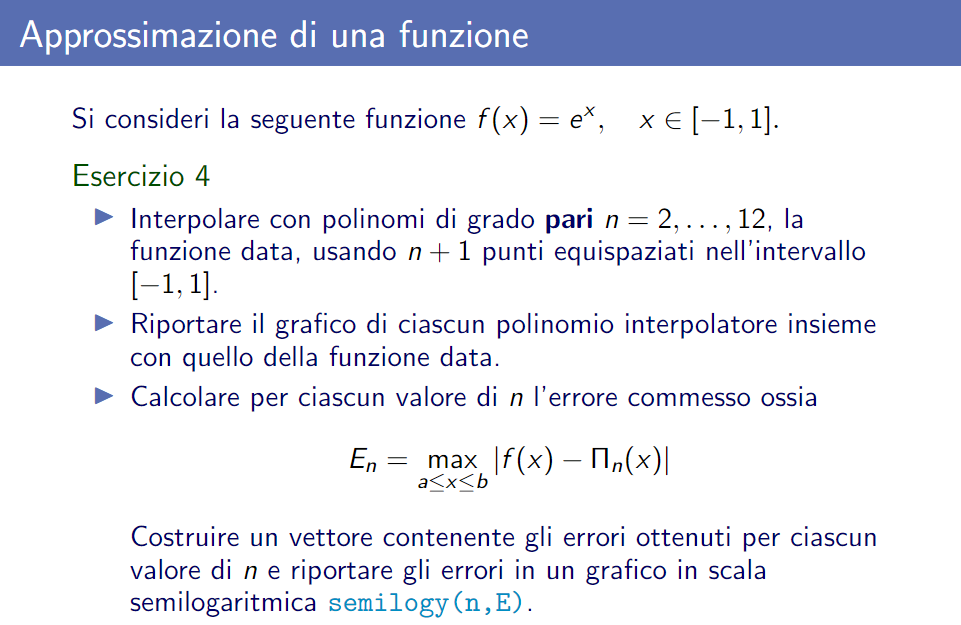

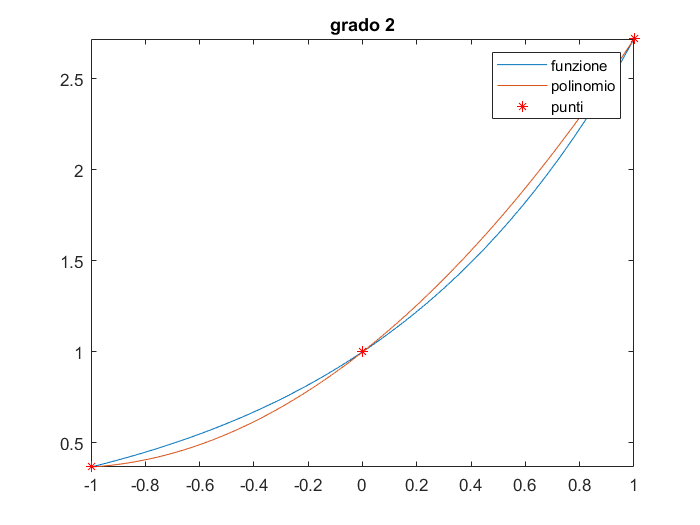

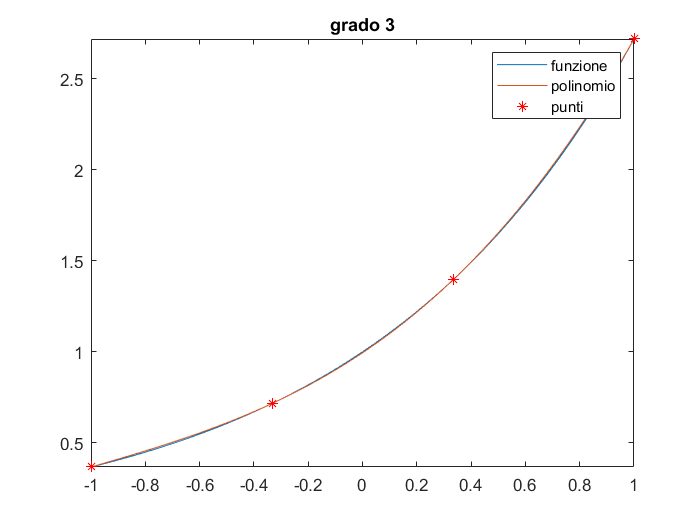

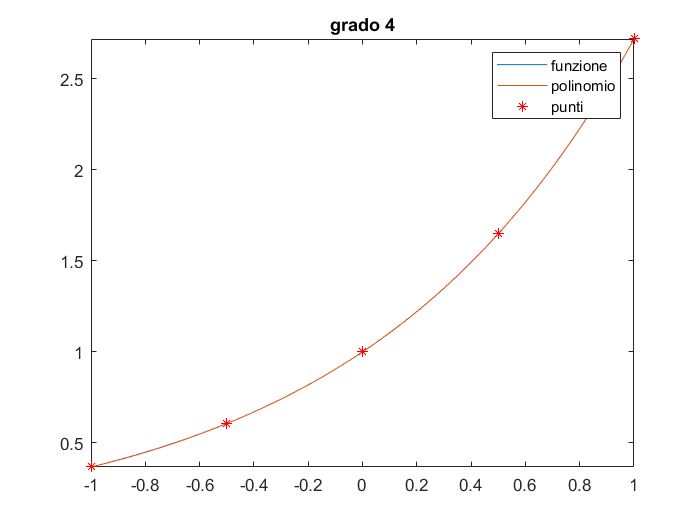


f = @(x) exp(x);
E =[];
for n = 2:1:4
    figure()
    fplot(f,[-1 1])
    hold on
    xp = linspace(-1,1,n+1);
    c = polyfit(xp,f(xp),n);
    x = linspace(-1,1,101);
    p = polyval(c,x);
    plot(x,p)
    plot(xp,f(xp),"*r")
    title("grado " + n)
    legend("funzione","polinomio","punti")
    y = f(x);
    e = abs(y-p);
    E = [E e];
end

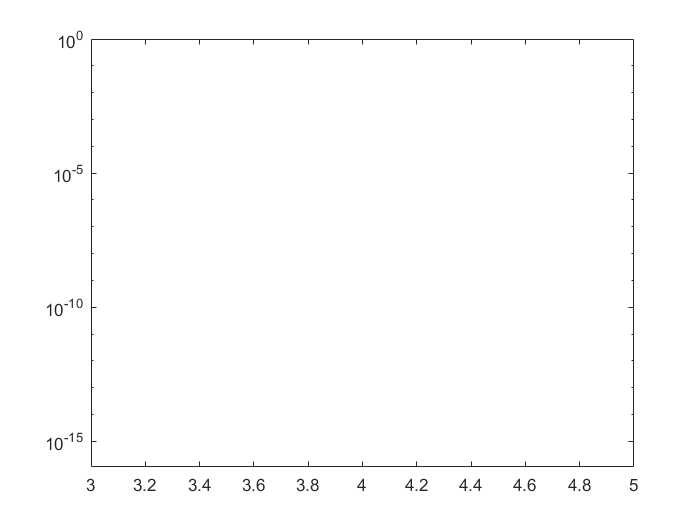

figure()
semilogy(n,E)

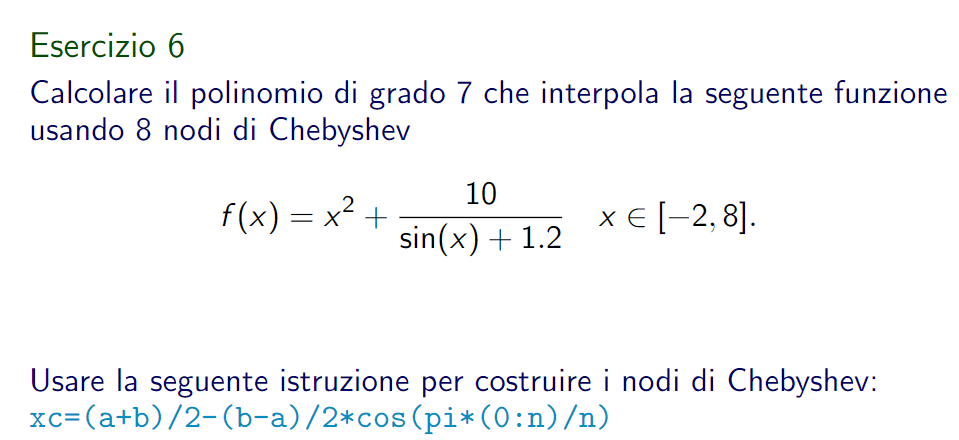

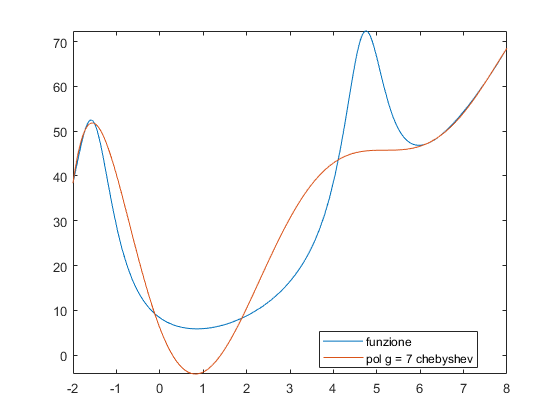

%in poly ci metto il grado mentre se faccio i nodi devo essere +1 rispetto
%al grado 
%se uso chebyshev è da 0:n che contiene gia il +1
clear all
close all


f = @(x) x.^2+10./(sin(x)+1.2);
[pc,xc,y,err] = chebyshev(f,-2,8,7);
x_ = linspace(-2,8,1000);
fplot(f,[-2 8])
hold on
plot(x_,polyval(pc,x_))
legend("funzione","pol g = 7 chebyshev","location","best")

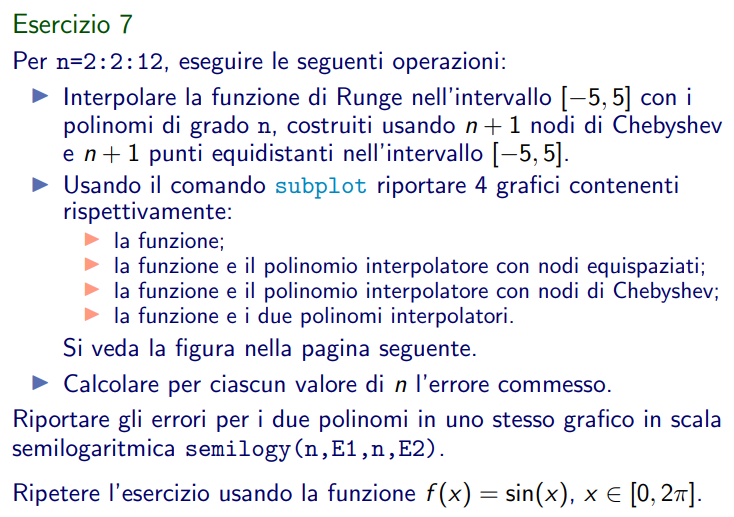

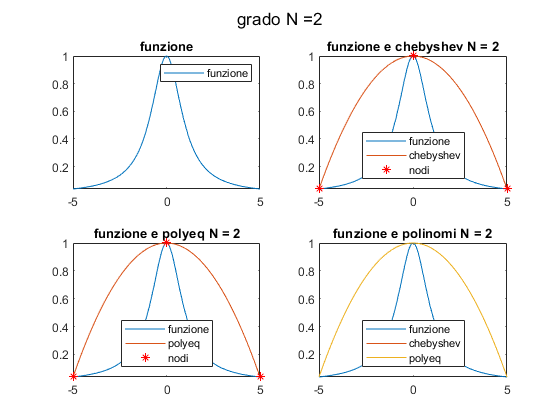

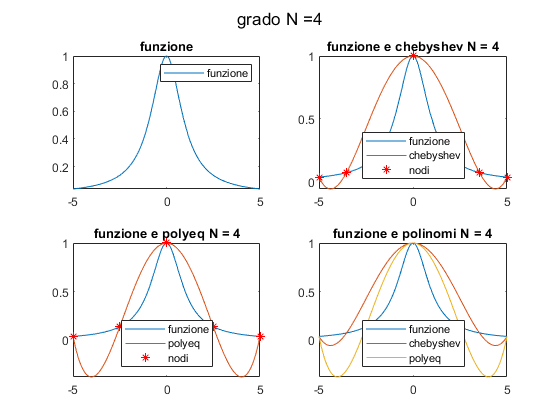

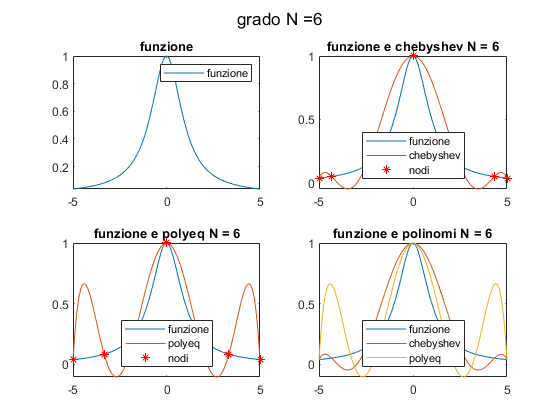

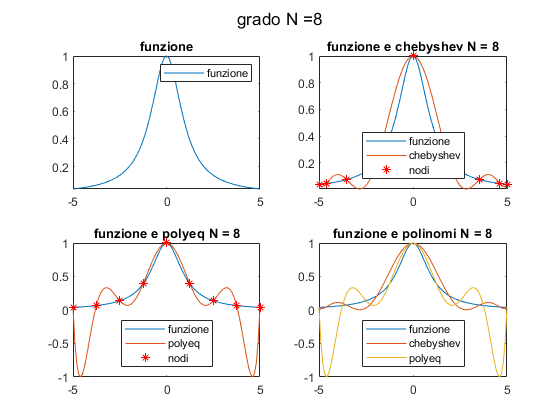

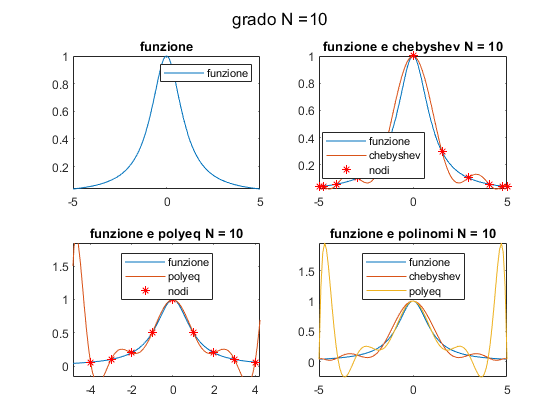

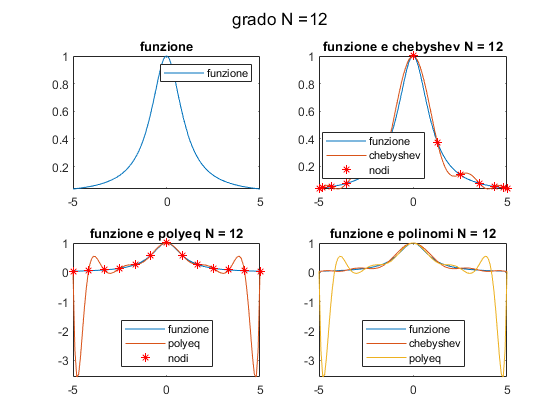

clear all
close all

f = @(x) 1./(1+x.^2);
z = linspace(-5,5,101);
a=-5;
b=5;
errc=zeros(1,length(2:2:12));
errp=zeros(1,length(2:2:12));
for n=2:2:12
    [pc,xc,yc,errc(n/2)]=chebyshev(f,a,b,n);
    [pp,xp,yp,errp(n/2)]=calcPoly(f,a,b,n);
    
    figure(n)
    sgtitle("grado N ="+n)
    
    subplot(2,2,1)
    fplot(f,[-5 5])
    hold on
    legend("funzione")
    title("funzione")
    
    subplot(2,2,2)
    fplot(f,[-5 5])
    hold on
    plot(z,polyval(pc,z))
    plot(xc,yc,"*r")
    legend("funzione","chebyshev","nodi","location","best")
    title("funzione e chebyshev N = "+n)
    subplot(2,2,3)
    
    fplot(f,[-5 5])
    hold on
    plot(z,polyval(pp,z))
    plot(xp,yp,'*r')
    legend("funzione","polyeq","nodi","location","best")
    title("funzione e polyeq N = "+n)
    subplot(2,2,4)
    
    fplot(f,[-5 5])
    hold on
    plot(z,polyval(pc,z))
    plot(z,polyval(pp,z))
    legend("funzione","chebyshev","polyeq","location","best")
    title("funzione e polinomi N = "+n)
end

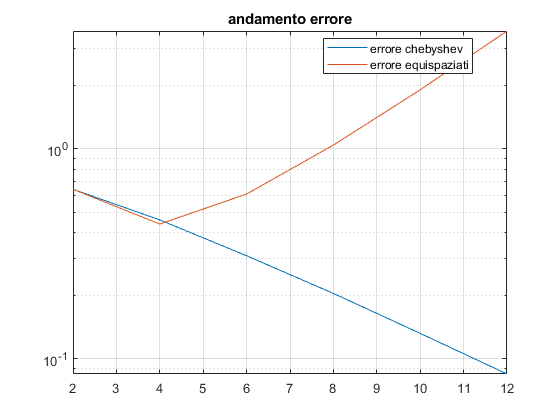

figure(20)
semilogy(2:2:12,errc,2:2:12,errp)
legend("errore chebyshev","errore equispaziati","Location","best")
title("andamento errore")
grid on

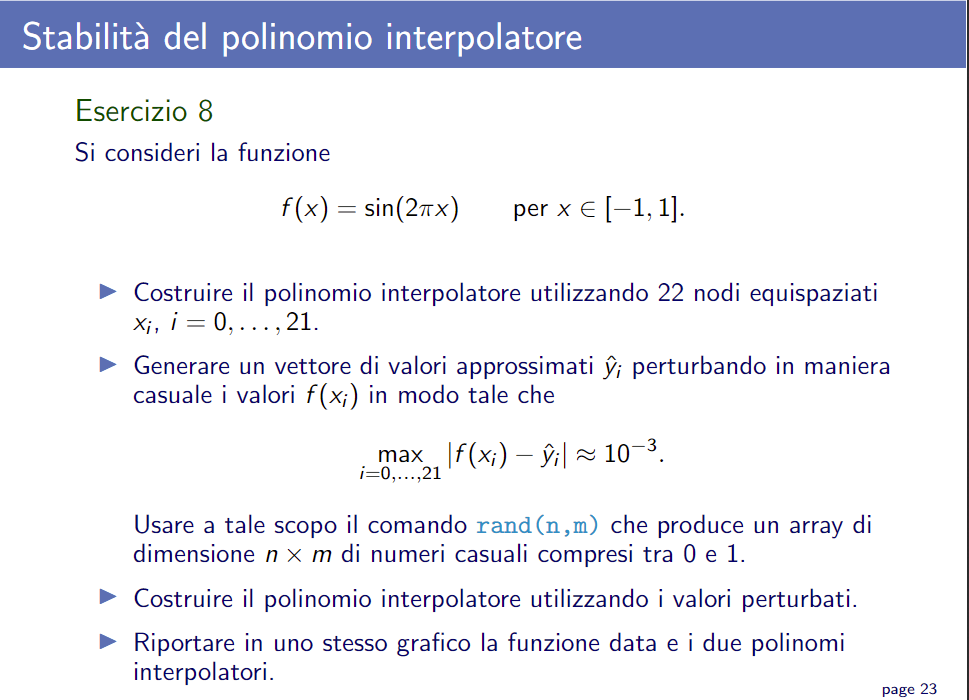

clear all
close all
f= @(x) sin(2*pi.*x);
n = linspace(-1,1,22);
c = polyfit(n,f(n),21);

x = linspace(-1,1,101);
p = polyval(c,x);
plot(x,p)

fe=f(n)-rand(1,22)*10^-3;
ce = polyfit(n,fe,21);

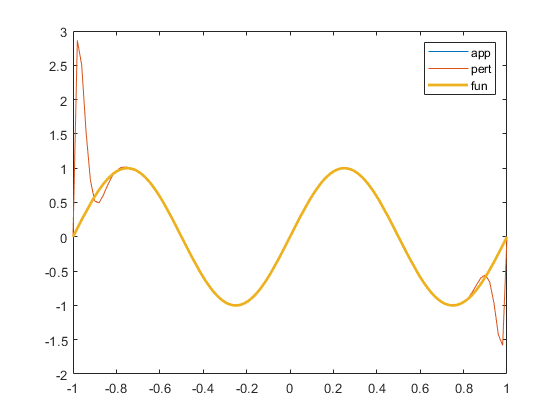

xe = linspace(-1,1,101);
pe = polyval(ce,xe);
hold on
plot(xe,pe)
fplot(f,[-1 1],"LineWidth",2)
legend("app","pert","fun")
hold off

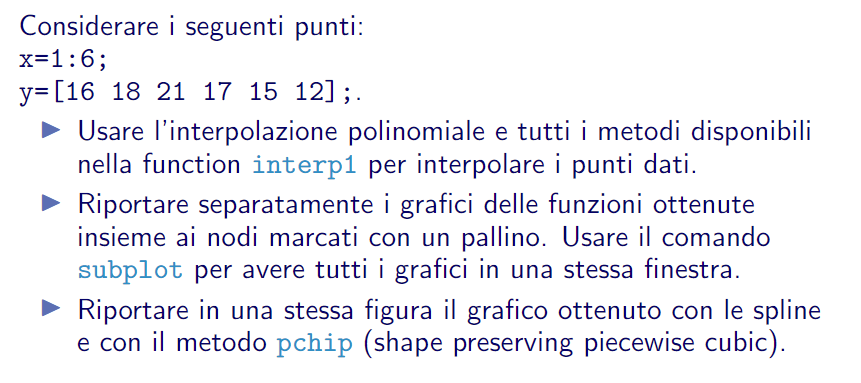

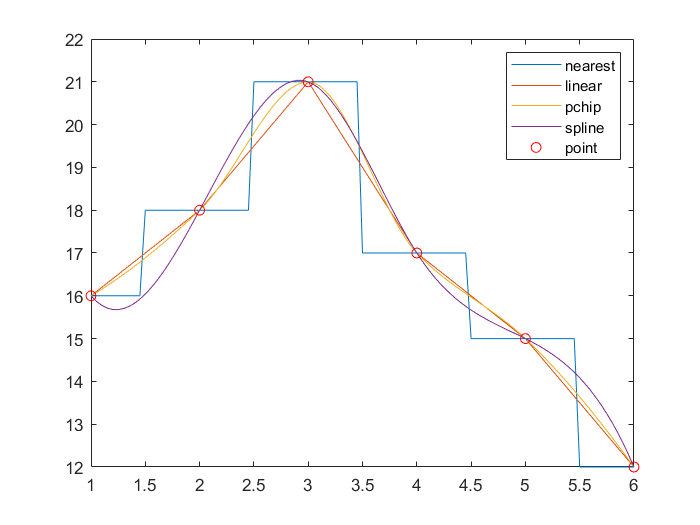

clear all
clear all
x=1:6;
y=[16 18 21 17 15 12];
z = linspace(1,6,101);
p1 = interp1(x,y,z,'nearest');
p2 = interp1(x,y,z,'linear');
p3 = interp1(x,y,z,'pchip');
p4 = interp1(x,y,z,'spline');
plot(z,p1,z,p2,z,p3,z,p4)
hold on
plot(x,y,'or')
legend('nearest','linear','pchip','spline','point')

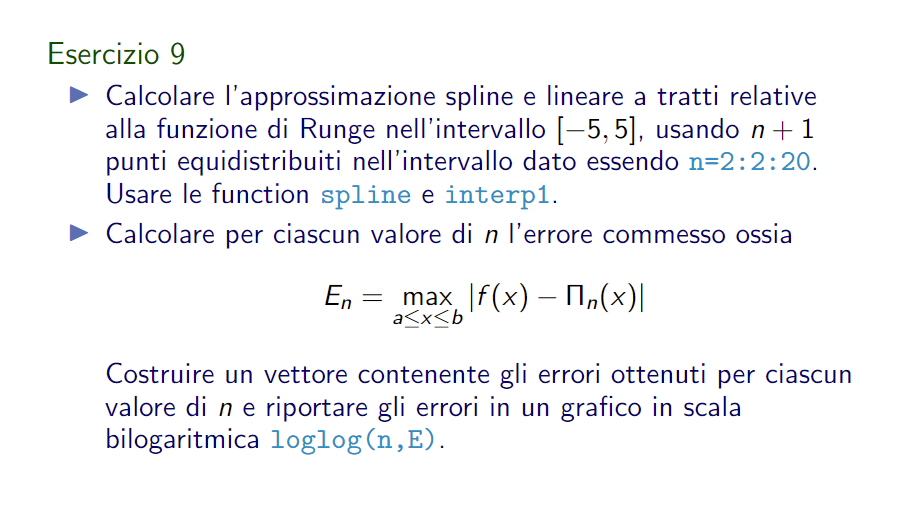

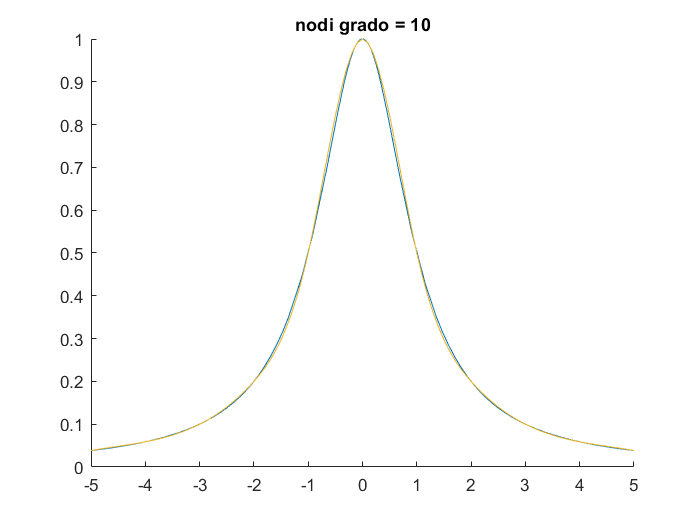

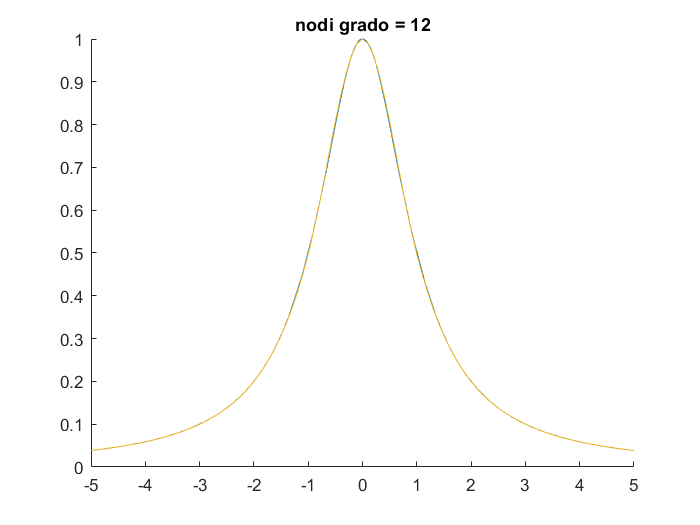

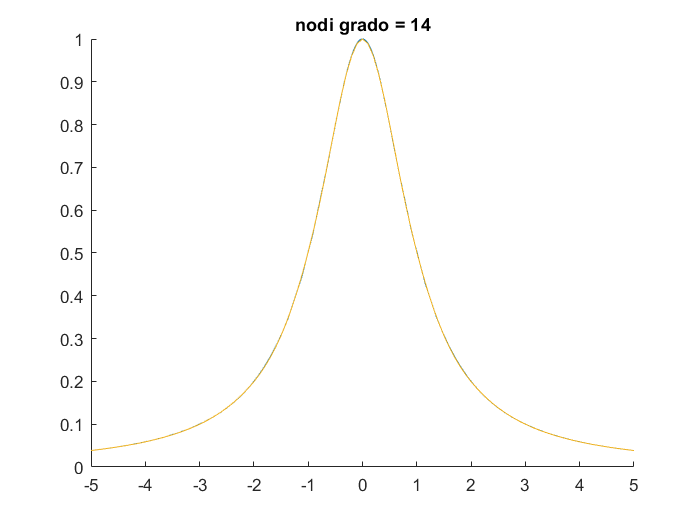

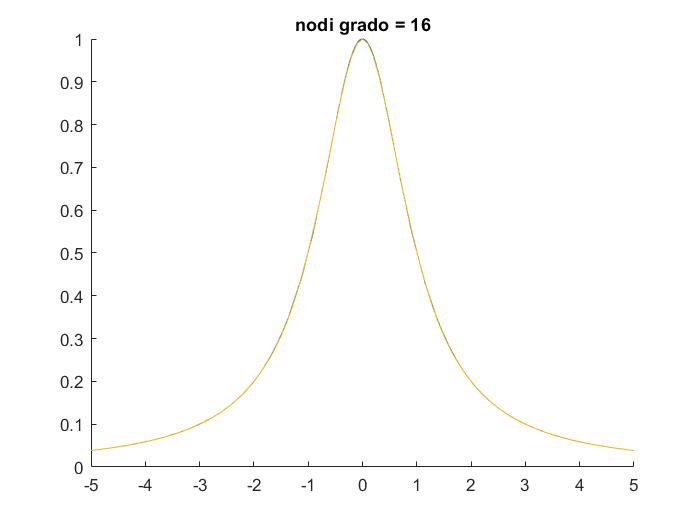

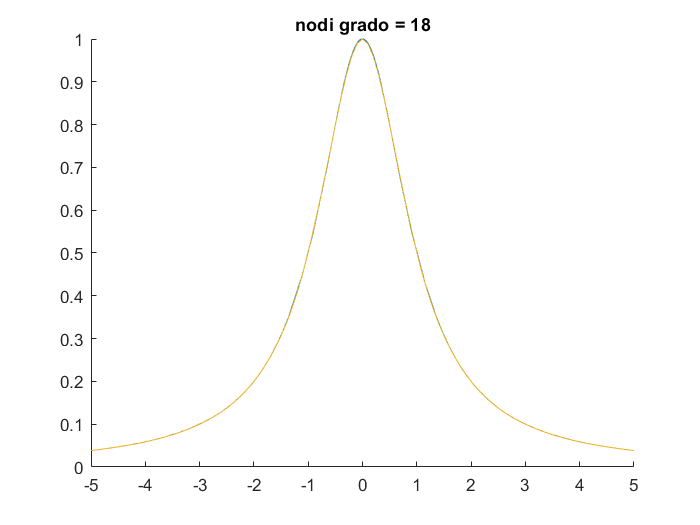

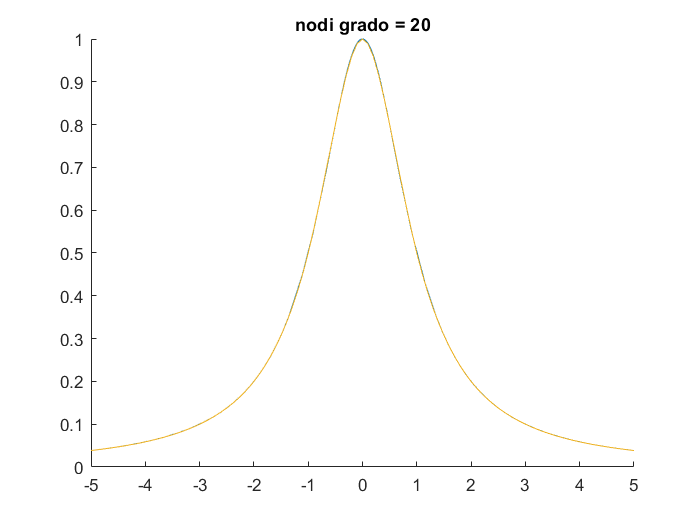

clear all
close all

f = @(x) 1./(1+x.^2);
z = linspace(-5,5,101);
E  = [];
E1 =[];
E2 = [];
for n = 2:2:20
    x = linspace(-5,5,n+1);
    y = f(x);
    figure()
    hold on
    c1 =spline(x,y,z);
    c = interp1(x,y,z,'spline');
    fplot(f,[-5 5])
    plot(z,c,z,c1)
    title("nodi grado = " +n)
    err = norm(c-c1);    
    E = [E err];
    E1 = [E1 norm(f(z)-c)];
    E2 = [E2 norm(f(z)-c1)];
end

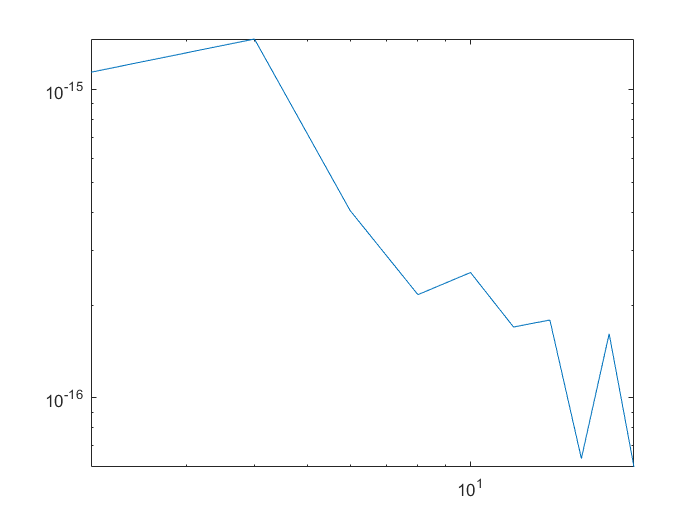

figure
loglog(2:2:20,E)

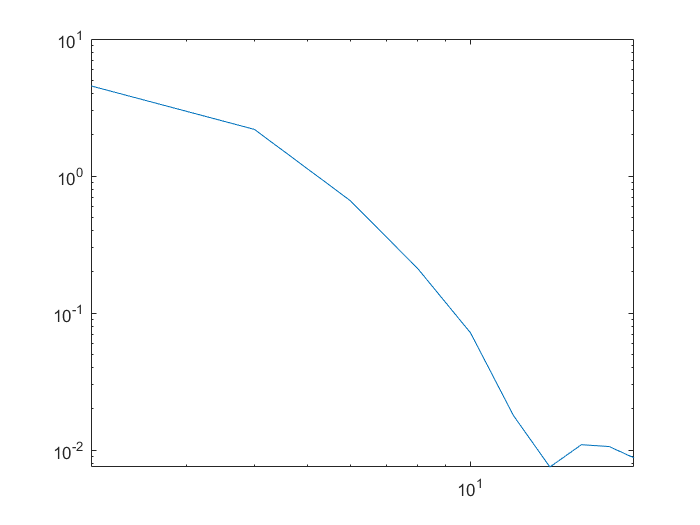

loglog(2:2:20,E1)

loglog(2:2:20,E2)

# Compito

## 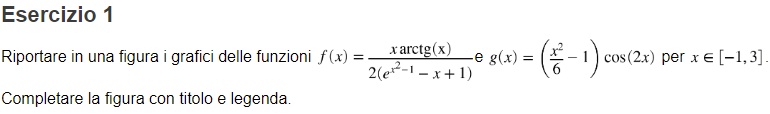

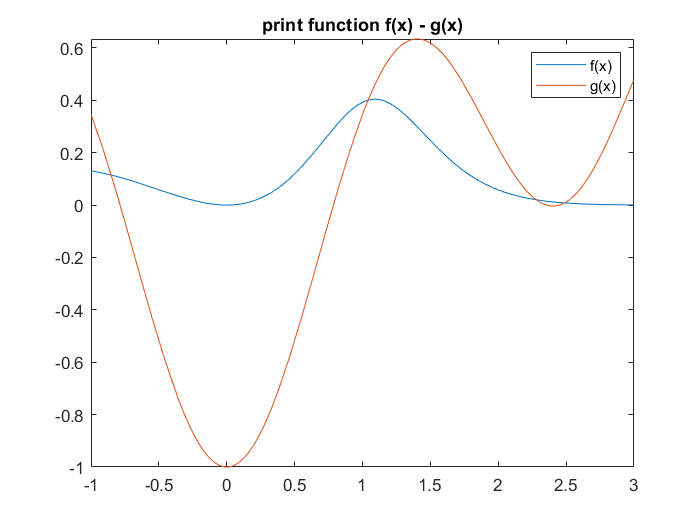


close all
clear all
f = @(x) (x.*atan(x))./(2*(exp(x.^2-1)-x+1));
g = @(x) ((x.^2)/6 -1).*(cos(2*x));
fplot(f,[-1 3])
hold on 
fplot(g,[-1 3])
legend('f(x)','g(x)')
title('print function f(x) - g(x)')

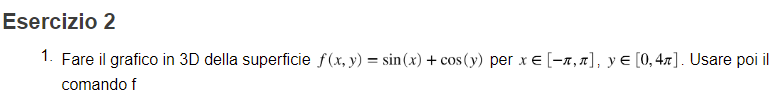

figure()
f = @(x,y) sin(x)+cos(y)

f = function_handle with value:
    @(x,y)sin(x)+cos(y)

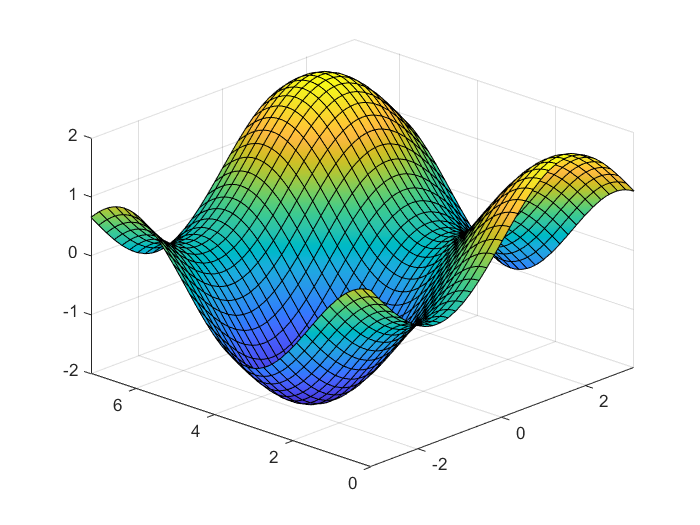

fsurf(f,[-pi,pi, 0,4+pi])